## **LOAD THE IMAGE**

clear all;
im = imread('PalazzoTe.jpg');

%rotate the image
img=imrotate(im, -90);

## **LOAD NECESSARY GEOMETRIC ELEMENTS**

K=load('elements\CALIBRATION MATRIX\K.mat').K

K = 1.0e+03 *

    3.3966         0    1.5527
         0    3.2321    2.2983
         0         0    0.0010



V_h=load('elements\VANISHING POINTS\V_h.mat').V_h

V_h = 1.0e+04 *

    1.0360
    0.4043
    0.0001



V=load('elements\VANISHING POINTS\V.mat').V

V = 1.0e+03 *

    0.2115
    6.5958
    0.0010


Build the IAC omega

omega=inv(K*K.')

omega =     0.0000   -0.0000   -0.0001
   -0.0000    0.0000   -0.0002
   -0.0001   -0.0002    1.7146


## **INTERSECT THE IMAGE OF THE ABSOLUTE CONIC AND THE LINE AT INFINITY TO COMPUTE THE CIRCULAR POINTS**

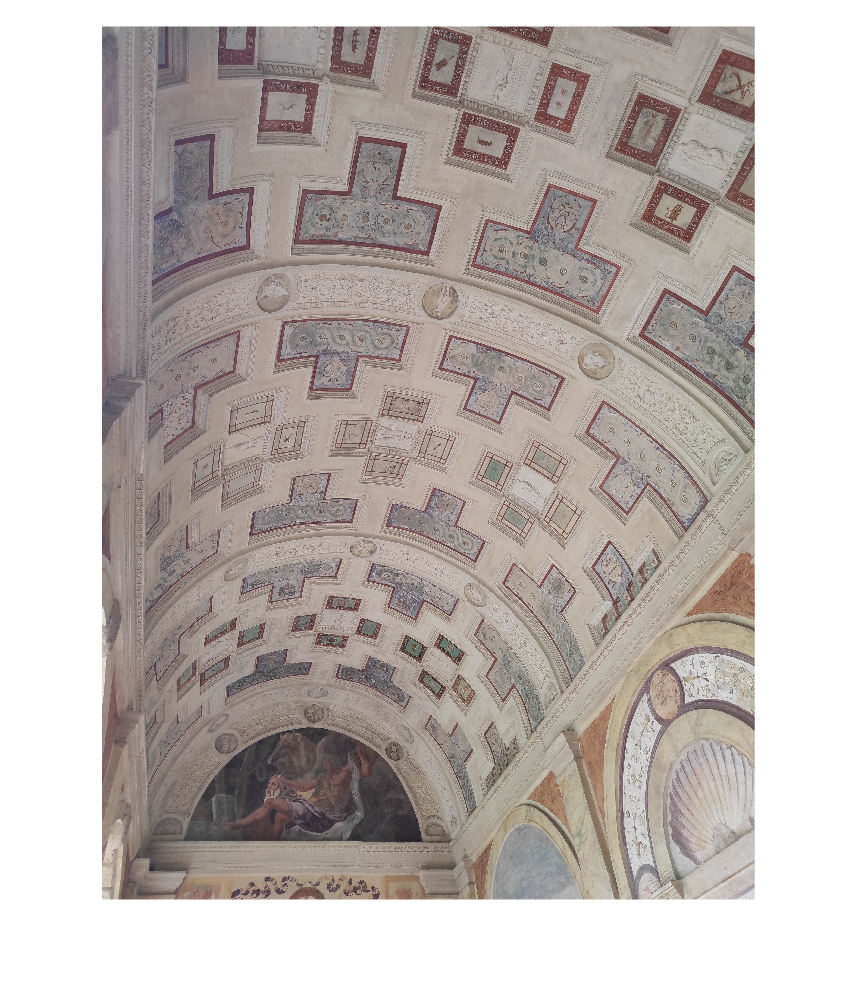

vanishing=line_through_two_pts(V,V_h, img,true);



[I,J]=conic_line_intersection(omega,vanishing,img,false)

I = 1.0e+03 *

   2.5810 + 5.0906i
   5.9998 - 1.2805i
   0.0010 + 0.0000i


J = 1.0e+03 *

   2.5810 - 5.0906i
   5.9998 + 1.2805i
   0.0010 + 0.0000i


## **RECONSTRUCT HOMOGRAPHY OF AXIAL PLANE**

imDCP=I*J.'+J*I.';
imDCP=imDCP./imDCP(3,3)

imDCP = 1.0e+07 *

    3.2576    0.8967    0.0003
    0.8967    3.7637    0.0006
    0.0003    0.0006    0.0000



[U,D,v]=svd(imDCP);

% To cancel out numerical errors
D(3,3)=1;
A=sqrt(D);

% Homographies
H=U*A;
Hsr=inv(H);

save('elements\HOMOGRAPHIES\HORIZONTAL PLANE\H.mat' , 'H')

DCP=[1,0,0; 
    0,1,0;
    0,0,0]

DCP =      1     0     0
     0     1     0
     0     0     0



check=H*DCP * H.'

check = 1.0e+07 *

    3.2576    0.8967    0.0003
    0.8967    3.7637    0.0006
    0.0003    0.0006    0.0000
